## Exercise 1

setup

clear
addpath("frffit"); addpath("Assignments")

f1 = 40;        %[Hz] frequency zeros
f2 = 40;        %[Hz] frequency poles
B1 = 0.1;      %damping zeros
B2 = 1;         %damping poles
num = [1/(2*pi*f1)^2 (2*B1)/(2*pi*f1) 1]

num =    1.5831e-05   7.9577e-04   1.0000e+00


den = [1/(2*pi*f2)^2 (2*B2)/(2*pi*f2) 1]

den =    1.5831e-05   7.9577e-03   1.0000e+00


b) Analysis time domain

t_end = 30; %[s]
stepsize = 0.001; %[s]
out = sim('one.slx') %running the model

out =   Simulink.SimulationOutput:

                  input: [1x1 timeseries] 
                 output: [1x1 timeseries] 
                   tout: [30001x1 double] 

     SimulationMetadata: [1x1 Simulink.SimulationMetadata] 
           ErrorMessage: [0x0 char] 


figure()
hold on
x = out.input

  timeseries

  Common Properties:
            Name: ''
            Time: [30001x1 double]
        TimeInfo: [1x1 tsdata.timemetadata]
            Data: [30001x1 double]
        DataInfo: 

y = out.output

  timeseries

  Common Properties:
            Name: ''
            Time: [30001x1 double]
        TimeInfo: [1x1 tsdata.timemetadata]
            Data: [30001x1 double]
        DataInfo: 

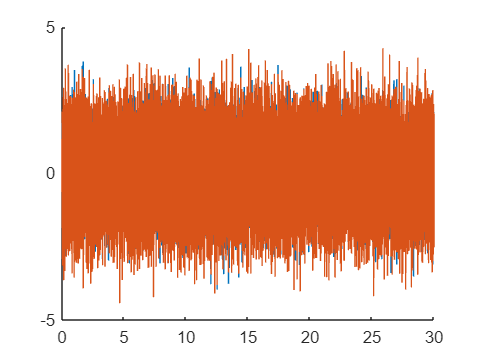

plot(x.Time,x.Data)
plot(y.Time,y.Data)

c) Analysis frequency domain

%spectral power analysis
windowsize = 0.5; %[s]
window = windowsize/stepsize

window =    500


figure()
[Pxx,F] = pwelch(x.Data,window)

Pxx =    1.6335e-01
   3.2174e-01
   3.1093e-01
   2.7859e-01
   2.4994e-01
   2.7088e-01
   3.3660e-01
   3.3654e-01
   3.3394e-01
   3.8654e-01


F =             0
   1.2272e-02
   2.4544e-02
   3.6816e-02
   4.9087e-02
   6.1359e-02
   7.3631e-02
   8.5903e-02
   9.8175e-02
   1.1045e-01


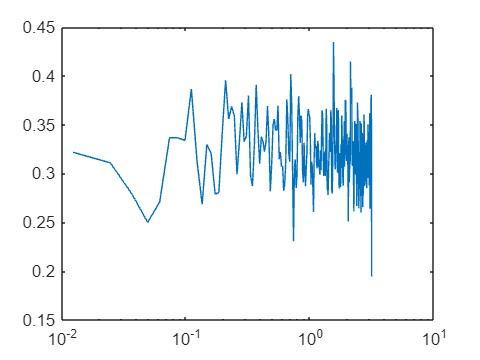

semilogx(F,abs(Pxx))


figure()
[Pxx,F] = pwelch(y.Data,window)

Pxx =    1.6461e-01
   3.1986e-01
   3.0043e-01
   2.5791e-01
   2.1676e-01
   2.1963e-01
   2.4652e-01
   2.2168e-01
   1.9121e-01
   1.9167e-01


F =             0
   1.2272e-02
   2.4544e-02
   3.6816e-02
   4.9087e-02
   6.1359e-02
   7.3631e-02
   8.5903e-02
   9.8175e-02
   1.1045e-01


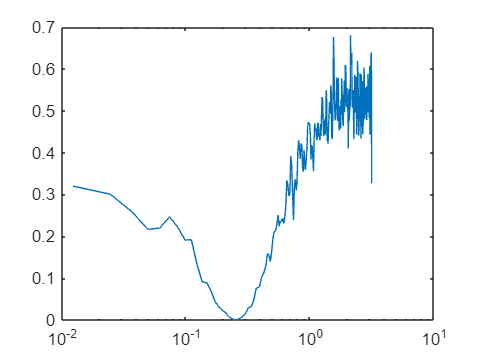

semilogx(F,abs(Pxx))


%periodogram
figure()
[pxx, F] = periodogram(x.Data)

pxx =    4.8792e-03
   2.5605e-01
   2.5164e-02
   1.7032e-01
   3.1277e-01
   1.6625e-02
   1.1045e+00
   5.2281e-01
   2.3348e-01
   6.7391e-01


F =             0
   1.9175e-04
   3.8350e-04
   5.7524e-04
   7.6699e-04
   9.5874e-04
   1.1505e-03
   1.3422e-03
   1.5340e-03
   1.7257e-03


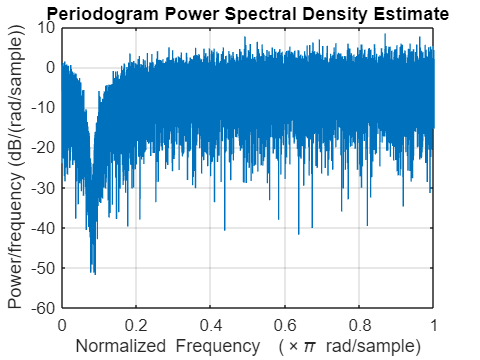

figure()
periodogram(y.Data)


%fft
[Fx, F] = fft(x.Data)

Error using fft
Too many output arguments.

semilogx(F,abs(Fx))
semilogx(F,angle(Fx))

%bode plots
figure()
tfestimate(x.Data,y.Data)

d) FRF 

X = periodogram(x.Data)

Unable to resolve the name 'x.Data'.

Y = periodogram(y.Data)
Fs = 1000
cpsd(x.Data,y.Data,[],[],[],Fs)


mscohere(x.Data,y.Data)